## Spearman R between IED TW delays and XC delays

clc; clear; close all;
addpath(fullfile('z_toolbox', 'Violinplot'));
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delay_Rmax_ED_as.mat'), ...
    'R_twxcD_rED_as', 'R_twxcD_as');
disp(mean(R_twxcD_as)); disp(std(R_twxcD_as));

    0.6792

    0.0060



disp(mean(R_twxcD_rED_as(:, 6))); disp(std(R_twxcD_rED_as(:, 6)));

    0.6239

    0.0041



figure('Units', 'centimeters', 'Position', [5, 5, 45, 24]);
subplot(2, 3, 1)
histogram(R_twxcD_as(:), 30, 'FaceColor', [1, 0.5, 0.5], 'Normalization', 'probability');
hold on;
histogram(R_twxcD_rED_as(:, 6), 30, 'FaceColor', [0.5, 0.5, 1], 'Normalization', 'probability');
hold off;
xlabel('Spearman Correlation'); 
ylabel('Probability'); 
ylim([0, 0.12]);
legend({'Unadjusted', 'Regress Distance'}, 'Box','off', 'Location', 'best');
set(gca, 'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_XC100ms_polyfit_delays_Rmax_ED_es.mat'), 'R_twxcD_rED', 'R_twxcD');
for nS = 1:length(R_twxcD)
    Rstr{nS} = 'Unadjusted'; 
    Rstr{47+nS} = 'Regress Distance';
end
R(1:47) = R_twxcD;
R(48:47*2) = R_twxcD_rED(:, 6);
disp(mean(R_twxcD)); disp(std(R_twxcD));

    0.6259

    0.1278



disp(mean(R_twxcD_rED(:, 6))); disp(std(R_twxcD_rED(:, 6)));

    0.5585

    0.1277



subplot(2, 3, 4);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Unadjusted', 'Regress Distance'}, ...
    'ViolinColor', [1, 0.5, 0.5; 0.5, 0.5, 1], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]);
ylim([0.25, 0.85]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Spearman R between IED TW delays and NA XC delays

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step6_NAxcorr_polyfit',  'NAnon6d0IED_XC100ms_polyfit_delays_Rmas_ED_as.mat'), ...
    'R_twxcD_rED_as', 'R_twxcD_as');
disp(mean(R_twxcD_as(:))); disp(std(R_twxcD_as(:)));

    0.2221

    0.0057



disp(mean(R_twxcD_rED_as(:, 6))); disp(std(R_twxcD_rED_as(:, 6)));

    0.1736

    0.0052



subplot(2, 3, 2);
histogram(R_twxcD_as(:), 30, 'FaceColor', [1, 0.5, 0.5], 'Normalization', 'probability');
hold on;
histogram(R_twxcD_rED_as(:, 6), 30, 'FaceColor', [0.5, 0.5, 1], 'Normalization', 'probability'); 
hold off;
xlabel('Spearman Correlation');
ylabel('Probability');
ylim([0, 0.12]);
legend({'Unadjusted', 'Regress Distance'}, 'Box','off', 'Location', 'best');
set(gca, 'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step6_NAxcorr_polyfit', 'NAnon6d0IED_XC100ms_polyfit_delays_Rmas_ED_es.mat'), ...
    'R_twxcD_res', 'R_twxcD');
disp(mean(R_twxcD)); disp(std(R_twxcD));

    0.3403

    0.1155



disp(mean(R_twxcD_res(:, 6))); disp(std(R_twxcD_res(:, 6)));

    0.2460

    0.1041



for nS = 1:length(R_twxcD)
    Rstr{nS} = 'Unadjusted'; 
    Rstr{47+nS} = 'Regress Distance';
end
R(1:47) = R_twxcD;
R(48:47*2) = R_twxcD_res(:, 6);
subplot(2, 3, 5);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Unadjusted', 'Regress Distance'}, ...
    'ViolinColor', [1, 0.5, 0.5; 0.5, 0.5, 1], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Spearman R between IED XC delays and NA XC delays

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step6_NAxcorr_polyfit', 'NAnon6d0IED_XC100ms_IEDxcD_polyfit_delays.mat'), ...
    'RxcD_rED_as', 'RxcD_as');
disp(mean(RxcD_as(:))); disp(std(RxcD_as(:)));

    0.3371

    0.0061



disp(mean(RxcD_rED_as(:, 6))); disp(std(RxcD_rED_as(:, 6)));

    0.3028

    0.0074



subplot(2, 3, 3);
histogram(RxcD_as(:), 30, 'FaceColor', [1, 0.5, 0.5], 'Normalization', 'probability');
hold on;
histogram(RxcD_rED_as(:, 6), 30, 'FaceColor', [0.5, 0.5, 1], 'Normalization', 'probability');
hold off;
xlabel('Spearman Correlation');
ylabel('Probability');
ylim([0, 0.12]);
legend({'Unadjusted', 'Regress Distance'}, 'Box','off', 'Location', 'best');
set(gca, 'Box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
load(fullfile('step6_NAxcorr_polyfit', 'NAnon6d0IED_XC100ms_IEDxcD_polyfit_delays.mat'), ...
    'RxcD', 'RxcD_rED');
disp(mean(RxcD(:))); disp(std(RxcD(:)));

    0.4923

    0.1420



disp(mean(RxcD_rED(:, 6))); disp(std(RxcD_rED(:, 6)));

    0.4183

    0.1355



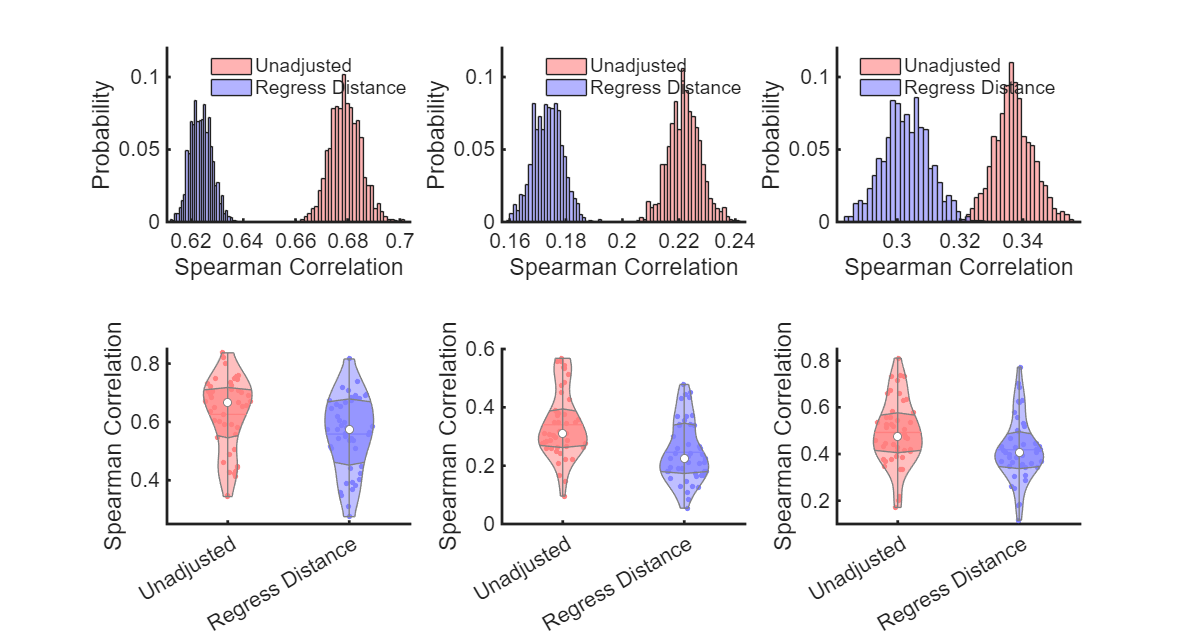

for nS = 1:length(RxcD)
    Rstr{nS} = 'Unadjusted';
    Rstr{47+nS} = 'Regress Distance';
end
R(1:47) = RxcD;
R(48:47*2) = RxcD_rED(:, 6);
subplot(2, 3, 6); 
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Unadjusted', 'Regress Distance'}, ...
    'ViolinColor', [1, 0.5, 0.5; 0.5, 0.5, 1], ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]);
ylim([0.1, 0.85]);
set(gca, 'box', 'off',  'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);